%%Figura 1
entrada = input('Digite el número de coeficientes: ');
num=num_coeficientes(entrada);
k=-num:num;

syms t f d e m;
Parte1=-t*exp((-1i*f*k)*t);
Parte2=t*exp((-1i*f*k)*t);
x=int (Parte1,t,d,e);
disp(x)

y=int (Parte2,t,e,m);
disp(y)

%%Sustitucion Simbolica
a=subs(x,{d,e,f},{-1,0,pi});
w=subs(y,{e,m,f},{0,1,pi});

t=a+w; 

m=simplify(t)

$$m = \begin{array}{l} \left(\begin{array}{ccccccccccccccccccc} \sigma_{1} & 0 & \sigma_{2} & 0 & \sigma_{3} & 0 & \sigma_{4} & 0 & -\frac{4}{\pi^{2}} & 1 & -\frac{4}{\pi^{2}} & 0 & \sigma_{4} & 0 & \sigma_{3} & 0 & \sigma_{2} & 0 & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{4}{81\,\pi^{2}}\\ \sigma_{2}=-\frac{4}{49\,\pi^{2}}\\ \sigma_{3}=-\frac{4}{25\,\pi^{2}}\\ \sigma_{4}=-\frac{4}{9\,\pi^{2}} \end{array}$$

r=abs(m); % Magnitud
v=angle(m); %  Angulo

subplot(2,1,1),stem(k,r,'m','LineWidth',1);
title('Modulo');
xlabel('t');
ylabel('x');
grid on

subplot(2,1,2),stem(k,v,'c','LineWidth',1);
title('Fase');
xlabel('t');
ylabel('x');
grid on


%%Figura 2
entrada = input('Digite el número de coeficientes: ');
num=num_coeficientes(entrada);
k=-num:num;

syms t f d e m;

Parte1=3/4*exp((-1i*f*k)*t);
Parte2=-1/4*exp((-1i*f*k)*t);
x=int (Parte1,t,d,e);
disp(x)

y=int (Parte2,t,e,m);
disp(y)

%%Sustitucion Simbolica
a=subs(x,{d,e,f},{0,3,pi/2});
w=subs(y,{e,m,f},{3,4,pi/2});

t=a+w; 

m=simplify(t)

$$m = \begin{array}{l} \left(\begin{array}{ccccccccccccccccccc} \frac{-\frac{2}{9}+\frac{2}{9}\,\mathrm{i}}{\pi } & 0 & \frac{\frac{2}{7}+\frac{2}{7}\,\mathrm{i}}{\pi } & \sigma_{1} & \frac{-\frac{2}{5}+\frac{2}{5}\,\mathrm{i}}{\pi } & 0 & \frac{\frac{2}{3}+\frac{2}{3}\,\mathrm{i}}{\pi } & \frac{2\,\mathrm{i}}{\pi } & \frac{-2+2\,\mathrm{i}}{\pi } & 2 & \frac{-2-2\,\mathrm{i}}{\pi } & -\frac{2\,\mathrm{i}}{\pi } & \frac{\frac{2}{3}-\frac{2}{3}\,\mathrm{i}}{\pi } & 0 & \frac{-\frac{2}{5}-\frac{2}{5}\,\mathrm{i}}{\pi } & -\sigma_{1} & \frac{\frac{2}{7}-\frac{2}{7}\,\mathrm{i}}{\pi } & 0 & \frac{-\frac{2}{9}-\frac{2}{9}\,\mathrm{i}}{\pi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\mathrm{i}}{3\,\pi } \end{array}$$

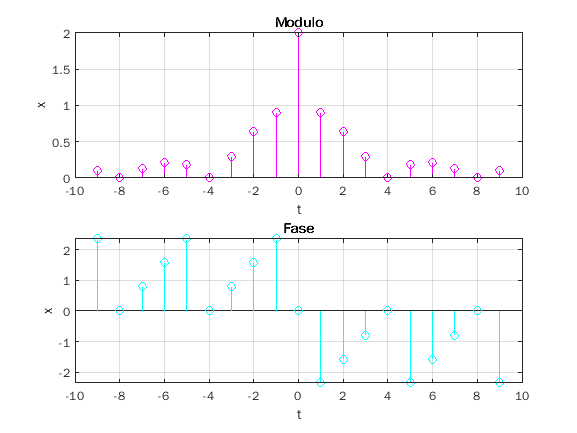

r=abs(m); 
v=angle(m); 

subplot(2,1,1),stem(k,r,'m','LineWidth',1);
title('Modulo');
xlabel('t');
ylabel('x');
grid on

subplot(2,1,2),stem(k,v,'c','LineWidth',1);
title('Fase');
xlabel('t');
ylabel('x');
grid on